# Operating point




V_vsc_mag=0.98;P_t=P_aero_0;x_sys=0.8768

x_sys = 0.8768

delta_vsc_0=asin((x_sys*P_t/V_vsc_mag))

delta_vsc_0 = 0.5667

delta_vsc_0*180/pi

ans = 32.4672

V_vsc=V_vsc_mag*(cos(delta_vsc_0)+1i*sin(delta_vsc_0))

V_vsc = 0.8268 + 0.5261i

Q_t=(V_vsc_mag^2-cos(delta_vsc_0))/x_sys

Q_t = 0.1331

I_vsc=conj((P_t+1i*Q_t))/(V_vsc_mag*(cos(delta_vsc_0)-1i*sin(delta_vsc_0)))

I_vsc = 0.5895 + 0.2141i

angle(I_vsc);ans*180/pi

ans = 19.9597

abs(I_vsc)

ans = 0.6271

V_t=V_vsc_mag*(cos(delta_vsc_0)+1i*sin(delta_vsc_0))+1i*I_vsc

V_t = 0.6127 + 1.1155i

delta_t=angle(V_t); delta_t*180/pi

ans = 61.2206

V_t_mag=abs(V_t)

V_t_mag = 1.2727



v_D0_vsc =real(V_vsc), v_Q0_vsc = imag(V_vsc)

v_D0_vsc = 0.8268

v_Q0_vsc = 0.5261

i_D0_vsc = real(I_vsc), i_Q0_vsc = imag(I_vsc)

i_D0_vsc = 0.5895

i_Q0_vsc = 0.2141

v_d0_t = real(V_t), v_q0_t = imag(V_t)

v_d0_t = 0.6127

v_q0_t = 1.1155

theta_0_vsc = 0.8354107558;
init_v_dq_t = [delta_t-delta_vsc_0, v_d0_t, v_q0_t]

init_v_dq_t =     0.5018    0.6127    1.1155



% dq/DqQ transformation matrices
P_meas = [v_D0_vsc v_Q0_vsc i_D0_vsc i_Q0_vsc]

P_meas =     0.8268    0.5261    0.5895    0.2141


Q_meas = [v_Q0_vsc -v_D0_vsc -i_Q0_vsc i_D0_vsc]

Q_meas =     0.5261   -0.8268   -0.2141    0.5895


v_D_t = [-v_q0_t*sin(delta_vsc_0)+v_d0_t*cos(delta_vsc_0) cos(delta_vsc_0) sin(delta_vsc_0) ]

v_D_t =    -0.0819    0.8437    0.5368


v_Q_t = [-v_d0_t*cos(delta_vsc_0)-v_q0_t*sin(delta_vsc_0) -sin(delta_vsc_0) cos(delta_vsc_0) ]

v_Q_t =    -1.1158   -0.5368    0.8437


v_d_vsc = [-v_Q0_vsc*sin(delta_vsc_0)-v_D0_vsc*cos(delta_vsc_0) cos(delta_vsc_0) -sin(delta_vsc_0) ]

v_d_vsc =    -0.9800    0.8437   -0.5368


v_q_vsc = [v_D0_vsc*cos(delta_vsc_0)-v_Q0_vsc*sin(delta_vsc_0) sin(delta_vsc_0) cos(delta_vsc_0) ]

v_q_vsc =     0.4152    0.5368    0.8437


i_d_vsc = [-i_Q0_vsc*sin(delta_vsc_0)-i_D0_vsc*cos(delta_vsc_0) cos(delta_vsc_0) -sin(delta_vsc_0) ]

i_d_vsc =    -0.6122    0.8437   -0.5368


i_q_vsc = [i_D0_vsc*cos(delta_vsc_0)-i_Q0_vsc*sin(delta_vsc_0) sin(delta_vsc_0) cos(delta_vsc_0) ]

i_q_vsc =     0.3824    0.5368    0.8437



T_vdq_DQ = [v_D_t; v_Q_t]

T_vdq_DQ =    -0.0819    0.8437    0.5368
   -1.1158   -0.5368    0.8437


T_vDQ_dq = [v_d_vsc; v_q_vsc]

T_vDQ_dq =    -0.9800    0.8437   -0.5368
    0.4152    0.5368    0.8437


T_iDQ_dq = [i_d_vsc; i_q_vsc]

T_iDQ_dq =    -0.6122    0.8437   -0.5368
    0.3824    0.5368    0.8437



T_PQ_meas = [P_meas; Q_meas]

T_PQ_meas =     0.8268    0.5261    0.5895    0.2141
    0.5261   -0.8268   -0.2141    0.5895



v_DQ0_t = T_vdq_DQ*init_v_dq_t'

v_DQ0_t =     1.0747
    0.0523


## p/angle controller



k_d_vsm= 70

k_d_vsm = 70

% 
H_vsm = 3

H_vsm = 3

T_vsm = tf([omega_nom/(2*H_vsm*l_f/omega_nom)*cos(delta_vsc_0)],[1 k_d_vsm/(2*H_vsm) omega_nom/(2*H_vsm*l_f/omega_nom)*cos(delta_vsc_0)])

T_vsm =
 
          1.315e05
  ------------------------
  s^2 + 11.67 s + 1.315e05
 
Continuous-time transfer function.
Model Properties



G_vsm = omega_nom/(2*H_vsm*s+k_d_vsm)

G_vsm =
 
   314.2
  --------
  6 s + 70
 
Continuous-time transfer function.
Model Properties



zeta_vsm = k_d_vsm/H_vsm*sqrt(2*H_vsm*x_sys/omega_nom)      

zeta_vsm = 3.0194

nf_vsm = sqrt(omega_nom/(2*H_vsm*x_sys))

nf_vsm = 7.7277

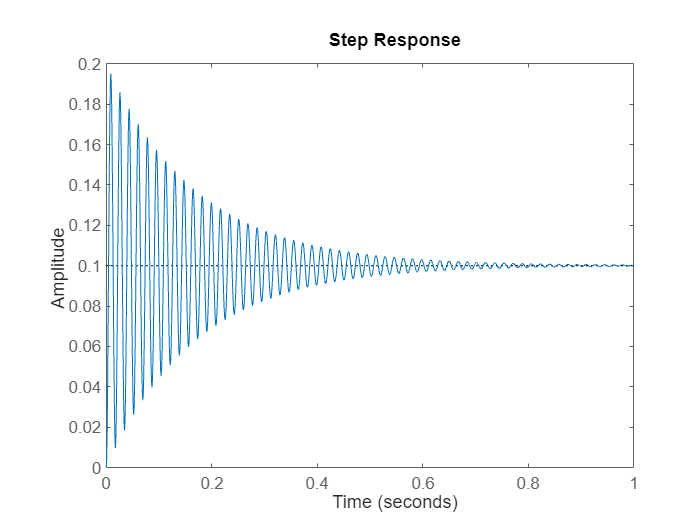

step(T_vsm*0.1)

## q controller droop


% ki_q = 2*pi*10

ki_q = 62.8319

% k_p_q_vsm = -0.05

k_p_q_vsm = -0.0500


% open loop

%closed loop 
T_q_vsm = tf([ki_q*k_p_q_vsm/x_sys],[1 ki_q+k_p_q_vsm*ki_q/x_sys])

T_q_vsm =
 
   -3.583
  ---------
  s + 59.25
 
Continuous-time transfer function.
Model Properties



%open loop Q_grid -> delta V_d_ref
G_qdroop = tf([ki_q*k_p_q_vsm],[1 ki_q])

G_qdroop =
 
   -3.142
  ---------
  s + 62.83
 
Continuous-time transfer function.
Model Properties


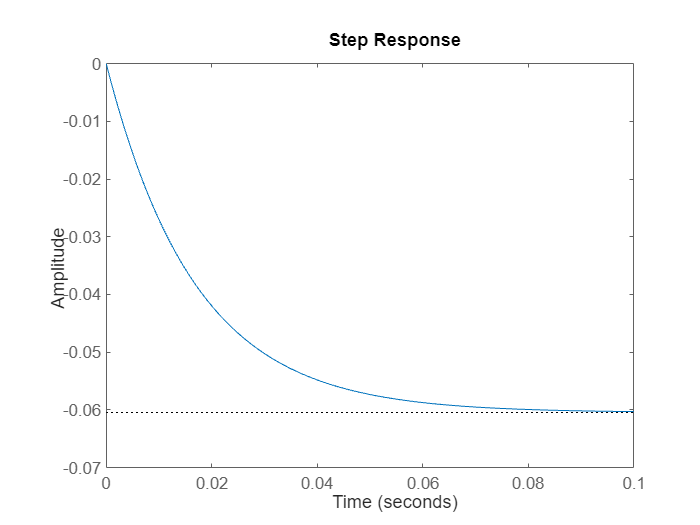


step(T_q_vsm)

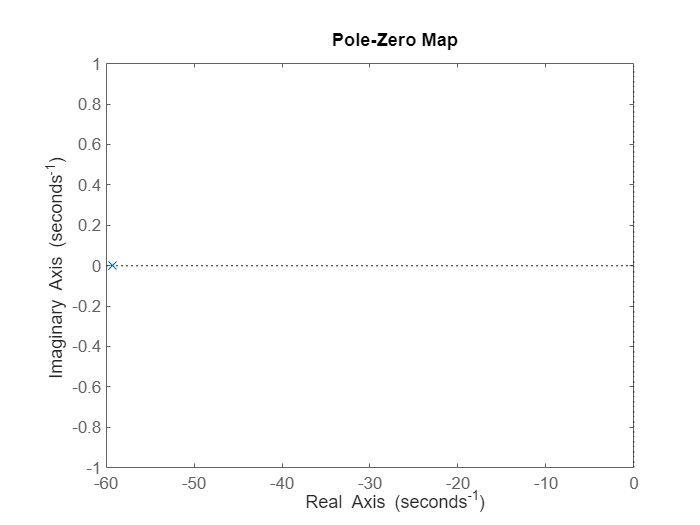

% step(T_e_vsm)

pzmap(T_q_vsm)

## current control

% s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


% ti = 5/f_sw

ti = 0.0017

% G_plant = 1/(s*l_f/omega_nom+r_f)

G_plant =
 
       314.2
  ----------------
  0.1056 s + 1.658
 
Continuous-time transfer function.
Model Properties


% kp = (l_f/omega_nom)/ti

kp = 0.1983

% ki = r_f/ti

ki = 3.1145

% G_cc = (kp*s+ki)/s

G_cc =
 
  0.1983 s + 3.115
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


% T_cc = G_plant*G_cc/(1+G_plant*G_cc)

T_cc =
 
         6.577 s^3 + 206.6 s^2 + 1623 s
  --------------------------------------------
  0.01115 s^4 + 6.927 s^3 + 209.4 s^2 + 1623 s
 
Continuous-time transfer function.
Model Properties


% 
% tf2ss([kp ki], [1 0])

ans = 0

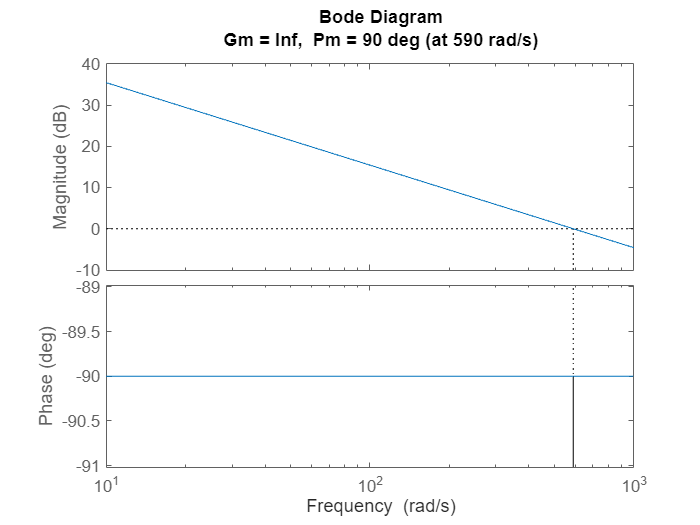

% margin(G_plant*G_cc)

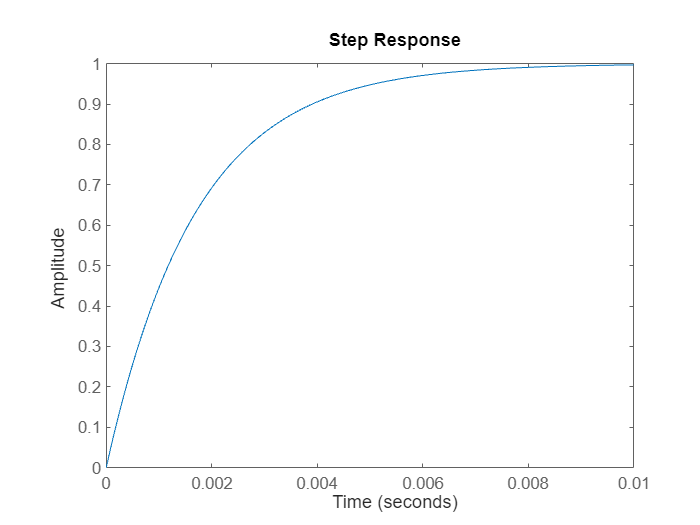

% step(T_cc)

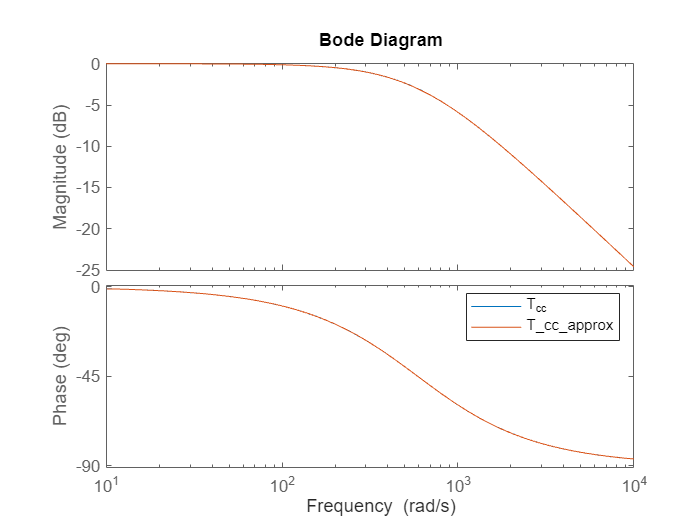

% bode(T_cc,1/(ti*s+1))
% legend('T_cc', 'T_cc_approx')

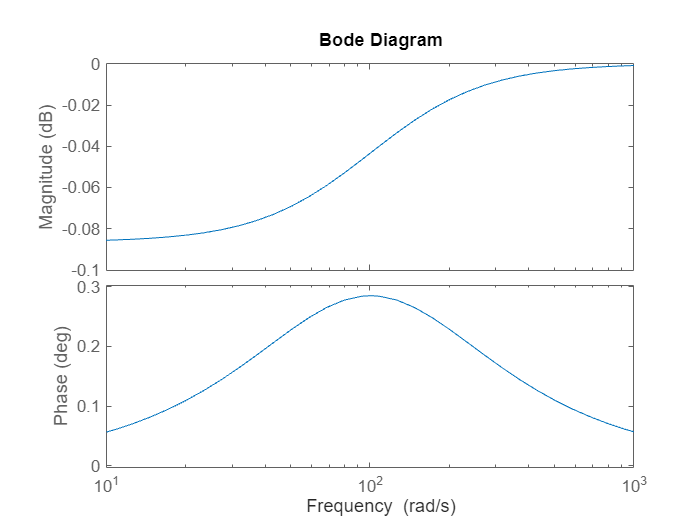

% bode(((0.01*s+1)/0.01)/(1+(0.01*s+1)/0.01)) 

% 
% 
% % G_plant = 1/(s*l_f/omega_nom+r_f)
% % G_grid_plant = 1/(s*x_sys/omega_nom+r_grid)
% % dq tf 
% i_DQ_plant = [s*l_f/omega_nom+r_f -l_f;
%               l_f s*l_f/omega_nom+r_f]

i_DQ_plant =
 
  From input 1 to output...
       0.1056 s + 1.658
   1:  ----------------
            314.2
 
   2:  0.1056
 
  From input 2 to output...
   1:  -0.1056
 
       0.1056 s + 1.658
   2:  ----------------
            314.2
 
Continuous-time transfer function.
Model Properties


% i_dq_ctrl = eye(2,2)*G_cc

i_dq_ctrl =
 
  From input 1 to output...
       0.1983 s + 3.115
   1:  ----------------
              s
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       0.1983 s + 3.115
   2:  ----------------
              s
 
Continuous-time transfer function.
Model Properties


%  i_dq_ff = [0 -l_f;
%             l_f 0]

i_dq_ff =          0   -0.1056
    0.1056         0


% i_DQ_grid = [s*x_sys/omega_nom+r_grid -x_sys;
%               x_sys  s*x_sys/omega_nom+r_grid]

i_DQ_grid =
 
  From input 1 to output...
       0.8768 s + 19.87
   1:  ----------------
            314.2
 
   2:  0.8768
 
  From input 2 to output...
   1:  -0.8768
 
       0.8768 s + 19.87
   2:  ----------------
            314.2
 
Continuous-time transfer function.
Model Properties


## voltage control



% z = 20

z = 20

% asind((1-ti*z)/(1+ti*z)) % phase margin

ans = 69.1356

% omega_c_vc = sqrt(z/ti)

omega_c_vc = 108.6278

% k_vc = (c_f/omega_nom)*omega_c_vc

k_vc = 0.0262

% G_vc = k_vc*(s+z)/s

G_vc =
 
  0.02618 s + 0.5235
  ------------------
          s
 
Continuous-time transfer function.
Model Properties


% %open
% G_forward_vc = k_vc/(ti*(c_f/omega_nom))*((s+z)/(s+1/ti))*1/s^2

G_forward_vc =
 
  6.409e04 s + 1.282e06
  ---------------------
      s^3 + 590 s^2
 
Continuous-time transfer function.
Model Properties


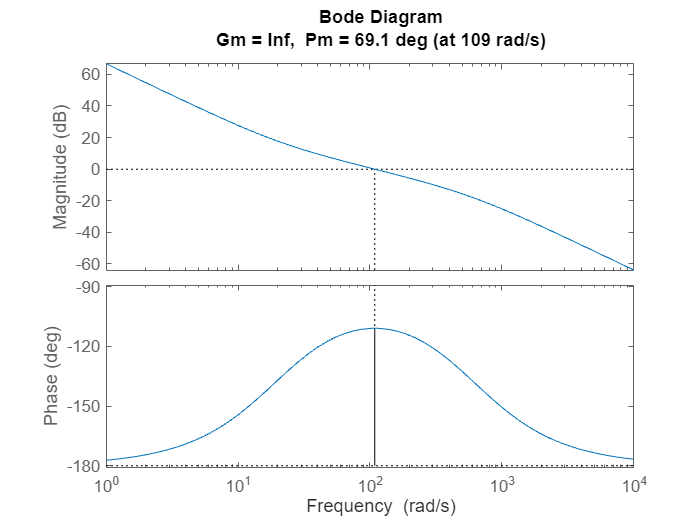

% margin(G_forward_vc)

% % closed
% T_vc = k/(ti*c_f)*((s+z)/(s+1/ti))*1/s^2/(1+k/(ti*c_f)*((s+z)/(s+1/ti))*1/s^2)

T_vc =
 
          2.338e05 s^4 + 1.426e08 s^3 + 2.759e09 s^2
  -----------------------------------------------------------
  s^6 + 1180 s^5 + 5.819e05 s^4 + 1.426e08 s^3 + 2.759e09 s^2
 
Continuous-time transfer function.
Model Properties


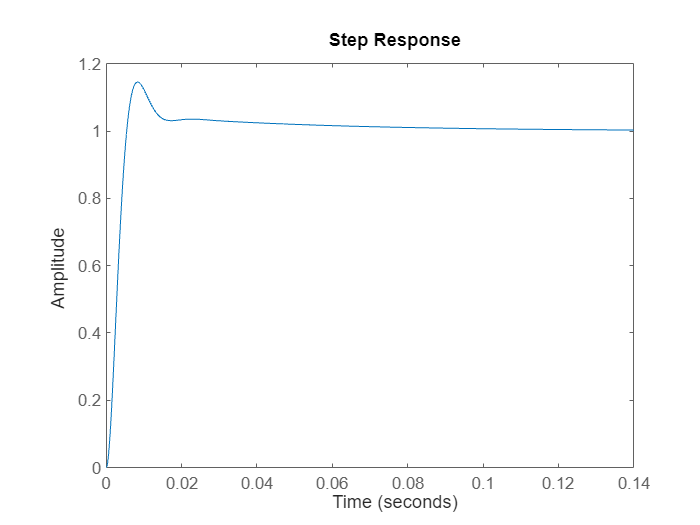

%     step(T_vc)

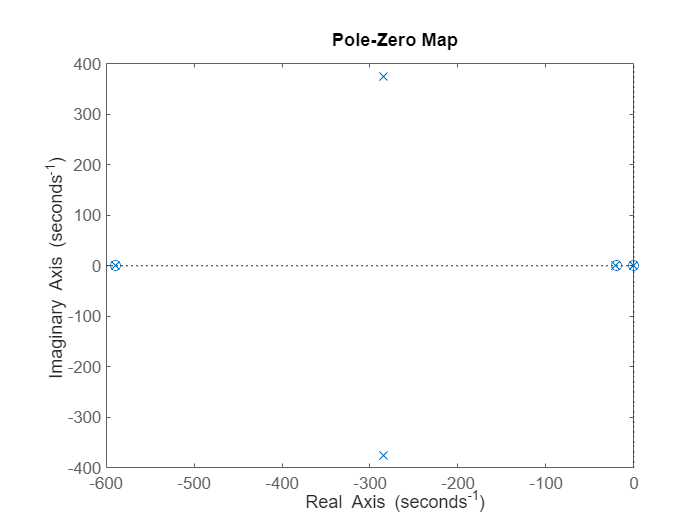

%     pzmap(T_vc)

% 
%  v_DQ_plant = [s*c_f/omega_nom -c_f;
%                 c_f s*c_f/omega_nom]

v_DQ_plant =
 
  From input 1 to output...
       0.0757 s
   1:  --------
        314.2
 
   2:  0.0757
 
  From input 2 to output...
   1:  -0.0757
 
       0.0757 s
   2:  --------
        314.2
 
Continuous-time transfer function.
Model Properties


%  v_dq_ctrl = eye(2,2)*G_vc

v_dq_ctrl =
 
  From input 1 to output...
       0.02618 s + 0.5235
   1:  ------------------
               s
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       0.02618 s + 0.5235
   2:  ------------------
               s
 
Continuous-time transfer function.
Model Properties


%  v_dq_ff = [0 -c_f;
%             c_f 0]

v_dq_ff =          0   -0.0757
    0.0757         0


## Detailed dc voltage controller

% 
% c_dc =0.00666540000000 % pu  0.47 % aggregated
% % negative 1 is steady state wind power pu
% % cross over frequency is 20 rad/s
%     zigma_dc = 2*l_f*(1)/(3*1^2)
% k0 = 1.5
% G_dc_pre =-k0*2/c_dc*(zigma_dc*s+1)/(s^2*(0.01*s+1)) 
% margin(G_dc_pre)
% step(G_dc_pre/(1+G_dc_pre))
% 
% n0 = 1/(10^(-13/20));
% 
% a = 50; 
% asind((a-1)/(a+1)) % phase margin
% p = sqrt(a)*23;
% N = -n0*(s+p/a)/(s+p)
% bode(N,N*G_dc_pre)
% margin(N*G_dc_pre)
% step(G_dc_pre*N/(1+G_dc_pre*N))
% 
% G_dc = N*k0/s 
% G_dc_num = get(G_dc,'Numerator')
% G_dc_denom = get(G_dc,'Denominator')
% T_dc = -2/c_f*(zigma_dc*s+1)/s
% T_dc_num = get(T_dc,'Numerator')
% T_dc_denom = get(T_dc,'Denominator')

##  dc voltage controller TV

% 
% C_dc_TV = 0.3 % F
% V_dc
% % negative 1 is steady state wind power pu
% % cross over frequency is 20 rad/s
% 
% G_dc_pre =1/(C_dc*s*V_dc) 
% margin(G_dc_pre)
% % step(G_dc_pre/(1+G_dc_pre))
% 
% kp_dc = 0.78;
% ki_dc = 0.85;
% margin(G_dc_pre*G_dc)
% G_dc = 1*(kp_dc + ki_dc/s)
% 
% 
% % a = 50; 
% % asind((a-1)/(a+1)) % phase margin
% % p = sqrt(a)*23;
% % N = -n0*(s+p/a)/(s+p)
% % bode(N,N*G_dc_pre)
% % margin(N*G_dc_pre)
% % step(G_dc_pre*N/(1+G_dc_pre*N))
% step(G_dc_pre*G_dc/(1+G_dc_pre*G_dc)*K_TP)
% G_dc_num = get(G_dc,'Numerator')
% G_dc_denom = get(G_dc,'Denominator')
% T_dc = G_dc_pre
% T_dc_num = get(T_dc,'Numerator')
% T_dc_denom = get(T_dc,'Denominator')

## simplified dc controller

c_dc = 0.47; % pu  aggregated
C_dc, c_dc*Cbase1v

C_dc = 1.9849

ans = 1.9797

% cross over frequency is 20 rad/s
dc_plant = -1/(c_dc/omega_nom)*1/s

dc_plant =
 
  -668.4
  ------
    s
 
Continuous-time transfer function.
Model Properties


kp_dc = 0.75 ;
ki_dc = 0.76;
G_dc = -1*(kp_dc + ki_dc/s)

G_dc =
 
  -0.75 s - 0.76
  --------------
        s
 
Continuous-time transfer function.
Model Properties


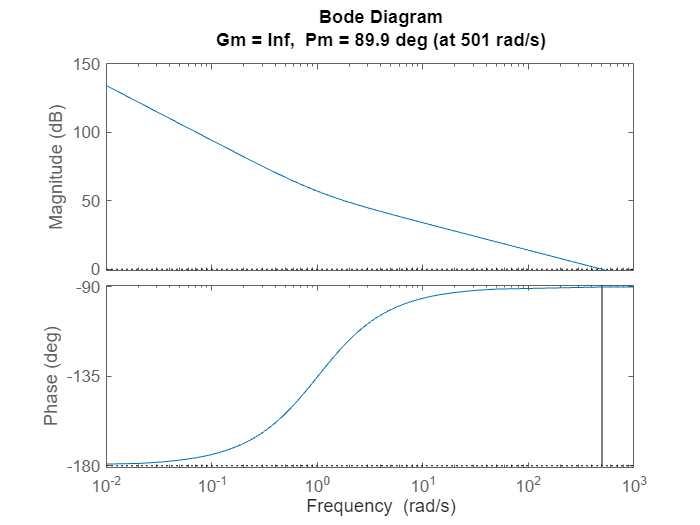


margin(G_dc*dc_plant)

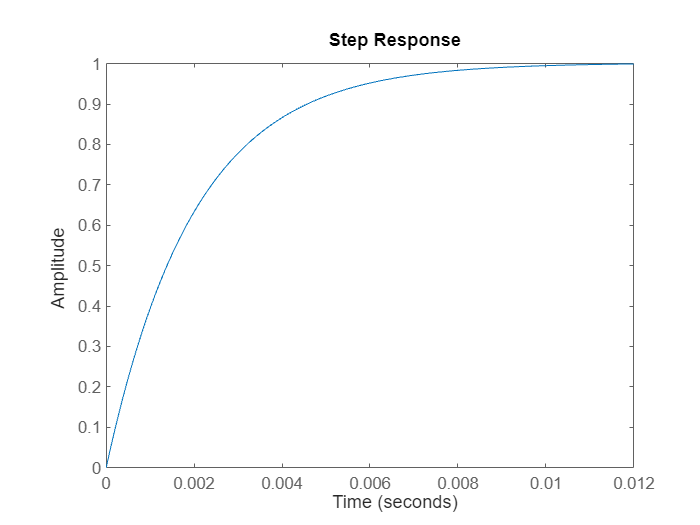

step(G_dc*dc_plant/(1+G_dc*dc_plant))

    
G_dc_num = get(G_dc,'Numerator')

G_dc_num = 1×1 cell array
    {[-0.7500 -0.7600]}


G_dc_denom = get(G_dc,'Denominator')

G_dc_denom = 1×1 cell array
    {[1 0]}


T_dc = dc_plant

T_dc =
 
  -668.4
  ------
    s
 
Continuous-time transfer function.
Model Properties


T_dc_num = get(T_dc,'Numerator')

T_dc_num = 1×1 cell array
    {[0 -668.4240]}


T_dc_denom = get(T_dc,'Denominator')    

T_dc_denom = 1×1 cell array
    {[1 0]}


## Linearized mppt

omega_WTR_0*omega_WTR_n

ans = 0.6399

mppt_gain = 3/2*rho*pi*R_WTR^5*C_p_opt/lambda_opt^3*(omega_WTR_0*omega_WTR_n)^2

mppt_gain = 3.7182e+07

% torsional vibration paper
% v_w_TV = 10
% lambda_opt_TV = 7
% c_p_opt_TV = 0.44
% R_WTR_TV = 63
% omega_WTR_0_TV = v_w_TV*lambda_opt_TV/R_WTR_TV
% omega_WTR_0_TV/1.27

% 0.5*rho*pi*R_WTR_TV^2*c_p_opt_TV*v_w_TV^3
% 0.5*rho*pi*R_WTR_TV^2*c_p_opt_TV*(omega_WTR_0_TV*R_WTR_TV/lambda_opt_TV)^3

15*pi/180

ans = 0.2618

v_w_0 = 0.872

v_w_0 = 0.8720

## Linearized two mass model

lambda_op = omega_WTR_0*R_WTR/(v_w_0*v_w_n)

lambda_op = 10.2401

k_tur=-0.04206446159

k_tur = -0.0421

A_m = 1/(2*H_WTR*s)

A_m =
 
    1
  -----
  4.2 s
 
Continuous-time transfer function.
Model Properties


A_g = 1/(2*H_gen*s)

A_g =
 
    1
  -----
  1.8 s
 
Continuous-time transfer function.
Model Properties


A_s = c_drt+k_drt/s

A_s =
 
  s + 280
  -------
     s
 
Continuous-time transfer function.
Model Properties



M_gr = A_s*((A_m*A_s)/(1+A_m*A_s-A_m*k_tur)-1)

M_gr =
 
  -74.09 s^6 - 2.075e04 s^5 - 207.8 s^4
  -------------------------------------
    74.09 s^6 + 18.38 s^5 + 4939 s^4
 
Continuous-time transfer function.
Model Properties


M_gr_num = get(M_gr,'Numerator')

M_gr_num = 1×1 cell array
    {[-74.0880 -2.0745e+04 -207.7648 0 0 0 0]}


M_gr_denom = get(M_gr,'Denominator')

M_gr_denom = 1×1 cell array
    {[74.0880 18.3820 4.9392e+03 0 0 0 0]}



K_Tomega = -P_aero_0/omega_WTR_0^2

K_Tomega = -0.9185

K_TP = 1/omega_WTR_0

K_TP = 1.2373

% Transfer functions

% v_dq = [G_vsm; 0; 0]

v_dq =
 
  From input to output...
         314.2
   1:  ----------
       4 s + 2500
 
   2:  0
 
   3:  0
 
Continuous-time transfer function.
Model Properties


% v_DQ_t = T_vdq_DQ*v_dq

v_DQ_t =
 
  From input to output...
         -25.72
   1:  ----------
       4 s + 2500
 
         -350.5
   2:  ----------
       4 s + 2500
 
Continuous-time transfer function.
Model Properties


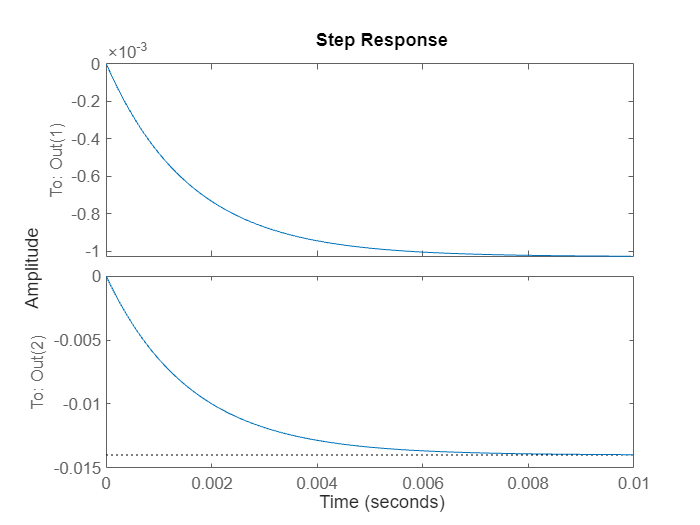

% step(v_DQ_t*0.1)

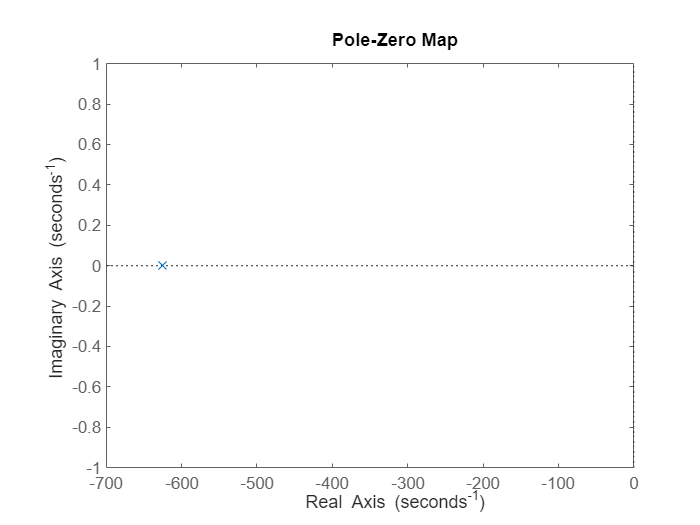

% Ggrid = i_DQ_grid;
% Gvplant = v_DQ_plant;
% Giplant = i_DQ_plant;
% pzmap(G_vsm)

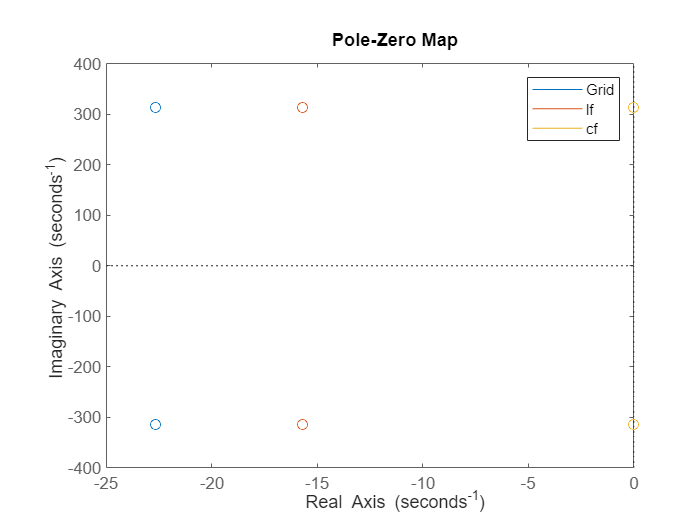

% pzmap(Ggrid,Giplant,Gvplant)
% legend Grid lf cf

% 
% % From v_DQ_t to v_DQ_vsc and i_DQ_vsc when v_Grid = 0
% 
% 
% i_DQ_vsc = Giplant^(-1)*v_DQ_t%(-Ggrid*Gvplant + eye(2,2))/(-Ggrid*Gvplant + Ggrid + Giplant)*v_DQ_t % 

i_DQ_vsc =
 
  From input to output...
                  -3.061e05 s^4 - 1.517e09 s^3 - 8.999e11 s^2 - 1.749e14 s - 8.136e16
   1:  -----------------------------------------------------------------------------------------
       16 s^6 + 2.101e04 s^5 + 1.069e07 s^4 + 4.47e09 s^3 + 1.524e12 s^2 + 2.346e14 s + 6.119e16
 
                  -4.172e06 s^4 - 2.708e09 s^3 - 4.746e11 s^2 - 2.544e14 s + 1.894e15
   2:  -----------------------------------------------------------------------------------------
       16 s^6 + 2.101e04 s^5 + 1.069e07 s^4 + 4.47e09 s^3 + 1.524e12 s^2 + 2.346e14 s + 6.119e16
 
Continuous-time transfer function.


% v_DQ_vsc =  Ggrid*i_DQ_vsc%Ggrid/(eye(2,2)+Ggrid*Gvplant)*i_DQ_vsc%Ggrid*(-Ggrid*Gvplant + eye(2,2))/((-Ggrid*Gvplant + Ggrid + Giplant)*(Ggrid*Gvplant + eye(2,2)))*v_DQ_t %

v_DQ_vsc =
 
  From input to output...
              -4.294e06 s^11 - 8.621e09 s^10 - 7.956e12 s^9 - 5.378e15 s^8 - 2.951e18 s^7 - 1.241e21 s^6 - 4.483e23 s^5 - 1.343e26 s^4 - 3.076e28 s^3 - 6.849e30 s^2 - 7.915e32 s - 1.308e35
   1:  --------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
       8.042e04 s^12 + 2.112e08 s^11 + 2.461e11 s^10 + 1.86e14 s^9 + 1.102e17 s^8 + 5.249e19 s^7 + 2.022e22 s^6 + 6.663e24 s^5 + 1.799e27 s^4 + 3.965e29 s^3 + 7.588e31 s^2 + 9.021e33 s + 1.176e36
 
              -5.853e07 s^11 - 1.175e11 s^10 - 1.067e14 s^9 - 6.985e16 s^8 - 3.734e19 s^7 - 1.528e22 s^6 - 5.341e24 s^5 - 1.565e27 s^4 - 3.456e29 s^3 - 7.559e31 s^2 - 8.405e33 s - 1.369e36
   2:  --------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------

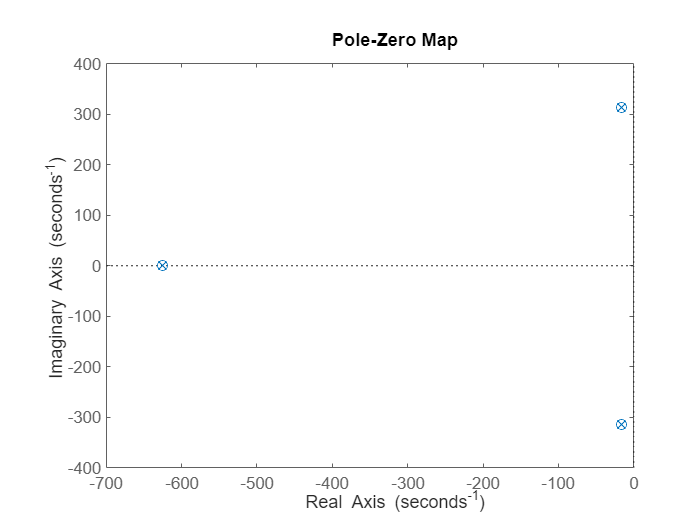

% 
% 
% pzmap(i_DQ_vsc)

% pzmap(v_DQ_vsc)

% 
% % Forward gain from Pref to Pvsc
% G_Pref_Pvsc = P_meas*[i_DQ_vsc; v_DQ_vsc]

G_Pref_Pvsc =
 
           -3.101e14 s^35 - 2.504e18 s^34 - 9.812e21 s^33 - 2.5e25 s^32 - 4.688e28 s^31 - 6.93e31 s^30 - 8.448e34 s^29 - 8.761e37 s^28 - 7.904e40 s^27 - 6.308e43 s^26 - 4.51e46 s^25 - 2.917e49 s^24 - 1.72e52 s^23 - 9.298e54 s^22 - 4.632e57 s^21 - 2.134e60 s^20 - 9.12e62 s^19 - 3.623e65 s^18 - 1.339e68 s^17 - 4.614e70 s^16 - 1.482e73 s^15 - 4.433e75 s^14 - 1.235e78 s^13 - 3.201e80 s^12 - 7.697e82 s^11 - 1.713e85 s^10 - 3.515e87 s^9 - 6.615e89 s^8 - 1.135e92 s^7 - 1.758e94 s^6 - 2.43e96 s^5 - 2.947e98 s^4 - 3.052e100 s^3 - 2.608e102 s^2 - 1.661e104 s - 7.238e105
  -------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------

% 
% % closed loop from Pref to Pvsc
% T_Pref_Pvsc = (G_Pref_Pvsc/(1+G_Pref_Pvsc))

T_Pref_Pvsc =
 
           -5.135e26 s^71 - 8.192e30 s^70 - 6.425e34 s^69 - 3.308e38 s^68 - 1.26e42 s^67 - 3.796e45 s^66 - 9.428e48 s^65 - 1.99e52 s^64 - 3.646e55 s^63 - 5.904e58 s^62 - 8.557e61 s^61 - 1.123e65 s^60 - 1.345e68 s^59 - 1.484e71 s^58 - 1.516e74 s^57 - 1.442e77 s^56 - 1.283e80 s^55 - 1.072e83 s^54 - 8.45e85 s^53 - 6.296e88 s^52 - 4.448e91 s^51 - 2.987e94 s^50 - 1.91e97 s^49 - 1.165e100 s^48 - 6.795e102 s^47 - 3.793e105 s^46 - 2.029e108 s^45 - 1.041e111 s^44 - 5.133e113 s^43 - 2.433e116 s^42 - 1.109e119 s^41 - 4.87e121 s^40 - 2.059e124 s^39 - 8.395e126 s^38 - 3.3e129 s^37 - 1.251e132 s^36 - 4.577e134 s^35 - 1.616e137 s^34 - 5.508e139 s^33 - 1.812e142 s^32 - 5.755e144 s^31 - 1.764e147 s^30 - 5.22e149 s^29 - 1.49e152 s^28 - 4.104e154 s^27 - 1.09e157 s^26 - 2.79e159 s^25 - 6.879e161 s^24 - 1.633e164 s^23 - 3.73e166 s^22 - 8.19e168 s^21 - 1.727e171 s^20 - 3.492e173 s^19 - 6.763e175 s^18 - 1.253e178 s^17 - 2.217e180 s^16 - 3.738e182 s^15 - 5.991e184 s^14 - 9.104e186 s^13 - 1.308

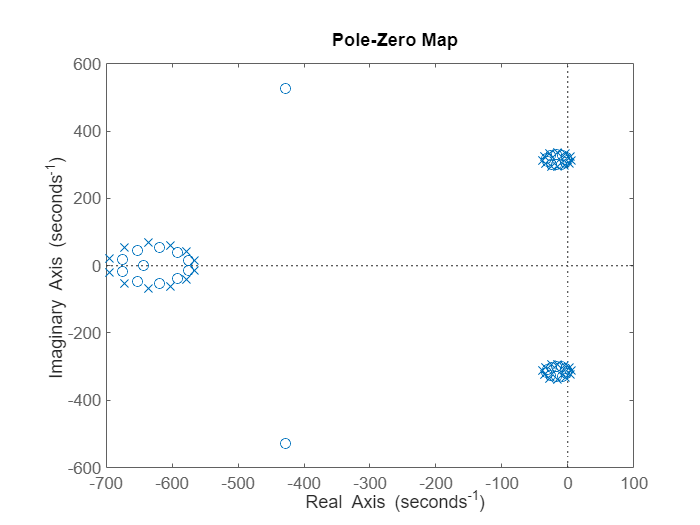

% 
% pzmap(G_Pref_Pvsc)

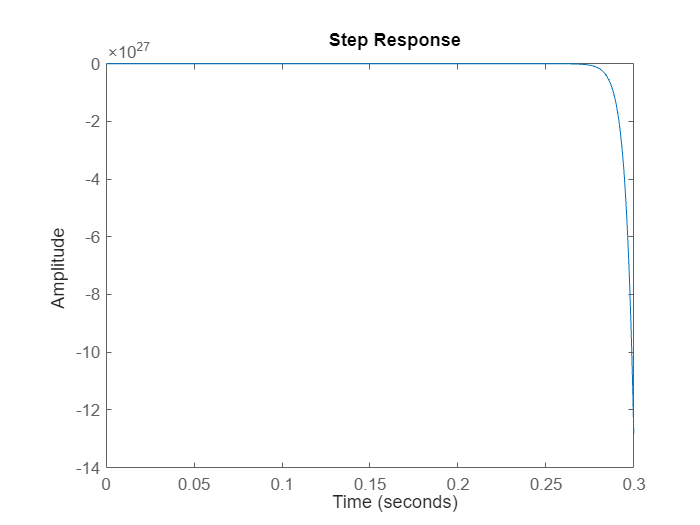

% step(T_Pref_Pvsc*0.1)

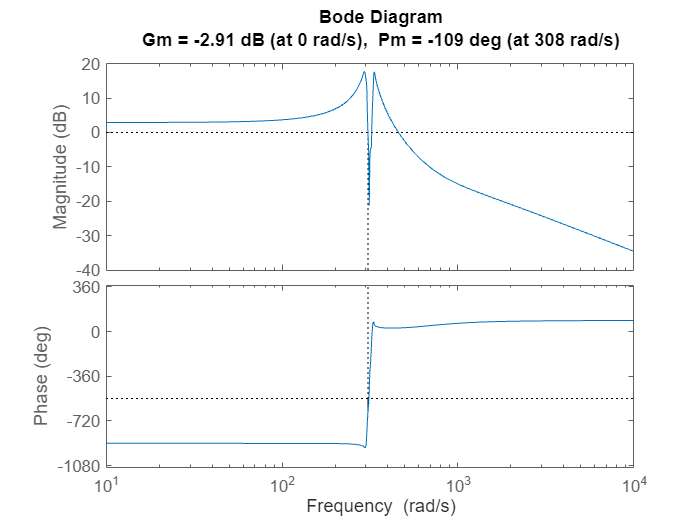

% margin(G_Pref_Pvsc)


% G_Pref_Pvsc_num = get(G_Pref_Pvsc,'Numerator');

sysFeedback =
 
       -3.101e14 s^35 - 2.504e18 s^34 - 9.812e21 s^33 - 2.5e25 s^32 - 4.688e28 s^31 - 6.93e31 s^30 - 8.448e34 s^29 - 8.761e37 s^28 - 7.904e40 s^27 - 6.308e43 s^26 - 4.51e46 s^25 - 2.917e49 s^24 - 1.72e52 s^23 - 9.298e54 s^22 - 4.632e57 s^21 - 2.134e60 s^20 - 9.12e62 s^19 - 3.623e65 s^18 - 1.339e68 s^17 - 4.614e70 s^16 - 1.482e73 s^15 - 4.433e75 s^14 - 1.235e78 s^13 - 3.201e80 s^12 - 7.697e82 s^11 - 1.713e85 s^10 - 3.515e87 s^9 - 6.615e89 s^8 - 1.135e92 s^7 - 1.758e94 s^6 - 2.43e96 s^5 - 2.947e98 s^4 - 3.052e100 s^3 - 2.608e102 s^2 - 1.661e104 s - 7.238e105
  -----------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------

poles_PrefPvsc = 1.0e+02 *

  -6.8053 + 0.0000i
  -6.7057 + 0.3050i
  -6.7057 - 0.3050i
  -6.4667 + 0.4906i
  -6.4667 - 0.4906i
  -6.1783 + 0.5313i
  -6.1783 - 0.5313i
  -5.8998 + 0.4172i
  -5.8998 - 0.4172i
  -5.7219 + 0.1593i


% G_Pref_Pvsc_demom = get(G_Pref_Pvsc,'Denominator');
% ss_Pref_Pvsc = tf2ss(G_Pref_Pvsc_num{1},G_Pref_Pvsc_demom{1});
% 
% sysFeedback = feedback(G_Pref_Pvsc,1)
% poles_PrefPvsc = pole(sysFeedback)

